# Stochastic Parameterization

This live script corresponds to section 3 of the paper *Parameterizing the impact of unresolved temperature variability on the large scale density field Part I: Theory* where we develop a stochastic parameterization of the effect of subgrid scale temperature and salinity fluctuations on the calculation of the large scale density. For the paper we compute all statistics for 73 snapshots, which corresponds to 1 model year. We have uploaded relevant fields at nominal 1 degree resolution. In this live script we demonstrate important calculations for one snapshot. Note that the statistical values in the paper are the average over 73 snapshots, so they do not exactly match the values in this script. All the code we used is included in the repoistory. The full data set is available upon request. 

## One snapshot: January 5th, 1989

load('0013_01_05_1degree_a.mat')
load('0013_01_05_1degree_b.mat')
load('0013_01_05_1degree_c.mat')
how_deep = 46 ; % only use the top 2km, or 46 model levels
scale = 10 ; % coarse grain from 0.1 degree to 1 degree
c = 0.20 ; % coefficient estimated in deterministic section

## Depth structure

% we only use the top 2km
z_t = z_t(1:how_deep);
dz = dz(1:how_deep);
dz2 = reshape(dz, 1, 1, how_deep);
DZ = repmat(dz2, [2400/scale, 3600/scale, 1]) ; % depth matrix

tbar = tbar(:,:,1:how_deep) ; % average temperature, top 2km
sgs_t_var = sgs_t_var(:,:,1:how_deep); % subgrid scale temperature variance, top 2km
sgs_t_var_mdl = len_grad(tbar) ; % when multiplied by c this is our model for sgs temp variance 

Calculate EOFs

cmask = ~isnan(sgs_t_var(:,:,how_deep) + sgs_t_var_mdl(:,:,how_deep)) ;
this_mask = cmask & abs(ulat < 60) ;

% EOF of SGS temperature variance: reshape data
sgs_t_reshape = reshape(sgs_t_var, [], how_deep) ; % contains NaNs
mask_reshape = reshape(this_mask, [], 1) ;
sgs_t_mat = sgs_t_reshape(mask_reshape, :) ;
num_el = sum(this_mask(:)) ;

% EOF of our model for SGS temperature variance: reshape data
sgs_t_mdl_reshape = reshape(sgs_t_var_mdl, [], how_deep) ; % contains NaNs
sgs_t_mdl_mat = sgs_t_mdl_reshape(mask_reshape, :) ;


% repeat 5 times
reps = 5;
EOF_diagnosed = zeros(how_deep, reps) ;
EOF_modeled = zeros(how_deep, reps) ;

for ii = 1:reps
    rng = randi([1 num_el],1,2000) ;
    % calculate EOF
    [~, EOFs, ~, ~, ~] = EOF(sgs_t_mat(rng, :)) ;
    [~, EOFs_mdl, ~, ~, ~] = EOF(sgs_t_mdl_mat(rng, :)) ;
    EOF_diagnosed(:,ii) = EOFs(:,1);
    EOF_modeled(:,ii) = EOFs_mdl(:,1);
end


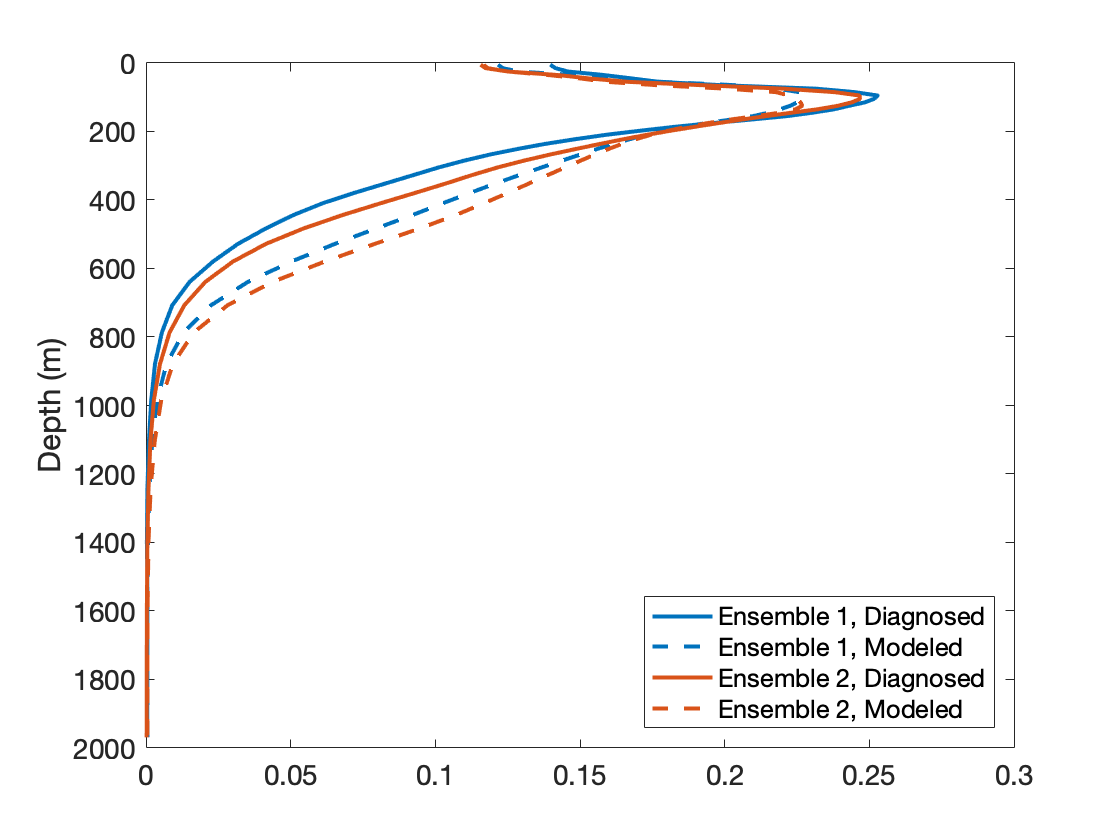

plot(-EOF_diagnosed(:,1), z_t(1:how_deep), 'LineWidth', 2); set(gca, 'YDir','reverse', 'FontSize', 14) ;
ylabel('Depth (m)') ;
%title('EOF')
hold on
plot(-EOF_modeled(:,1), z_t(1:how_deep),'--', 'LineWidth', 2, 'Color', [0 0.4470 0.7410]);
% sample 2
plot(-EOF_diagnosed(:,2), z_t(1:how_deep), 'LineWidth', 2, 'Color', [0.8500 0.3250 0.0980]);
plot(-EOF_modeled(:,2), z_t(1:how_deep),'--', 'LineWidth', 2, 'Color', [0.8500 0.3250 0.0980]);
%plot(EOF_modeled(:,3), z_t(1:how_deep),'--', 'LineWidth', 2, 'Color', [0.9290 0.6940 0.1250]);
legend('Ensemble 1, Diagnosed', 'Ensemble 1, Modeled', 'Ensemble 2, Diagnosed', 'Ensemble 2, Modeled', 'Location', 'southeast')
hold off

Project diagnosed subgrid scale temperature variance onto model for sgs temp variance

inner_prod = sum(sgs_t_var .* sgs_t_var_mdl .* DZ, 3);
norm_mean = c .* sum(sgs_t_var_mdl.^2 .* DZ, 3);
proj_field = inner_prod./norm_mean;

Calcuate the relative error and percent variance explained for the projection.

mask = ~isnan(proj_field) & abs(ulat)<60;
err = sgs_t_var - proj_field .* c.* sgs_t_var_mdl ; % error field
norm_err = sum(err.^2 .* DZ, 3) ; % norm of error field
norm_true = sum(sgs_t_var.^2 .* DZ, 3) ; % norm of sgs temp variance field
rel_err = sqrt(norm_err)./sqrt(norm_true) ; % relative error
fprintf('The percent of variance explained is %.1f\n', 100*nanmean(1-rel_err(mask).^2))

The percent of variance explained is 74.7


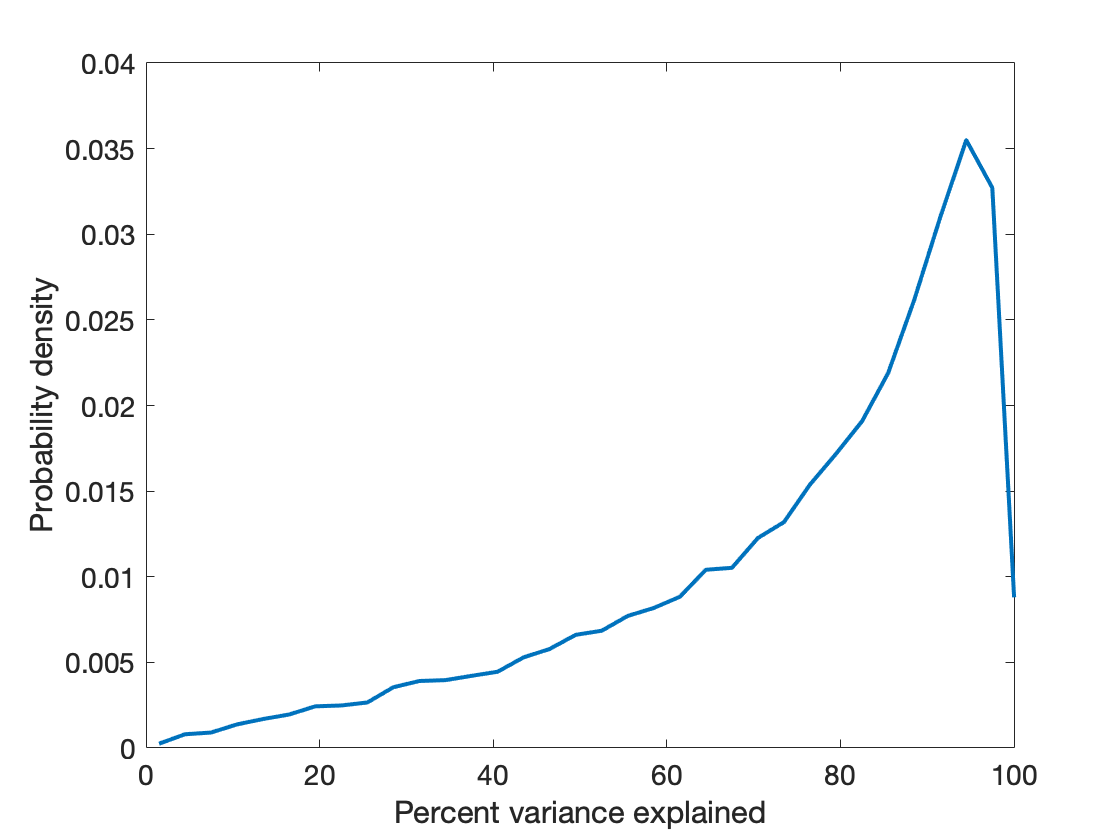


% plot percent variance explained
[N3,edges] = histcounts(100*(1-rel_err(mask).^2), 'Normalization','pdf');
centers = edges(2:end) - (edges(2)-edges(1))/2;
de3 = diff(edges);
N4 = N3 ./ sum(N3.*de3) ; % normalize so that pdf integrates to 1
plot(centers, N4, 'LineWidth', 2);
xlim([0, 100]) ;
set(gca, 'FontSize', 14)
ylabel('Probability density');
xlabel('Percent variance explained')

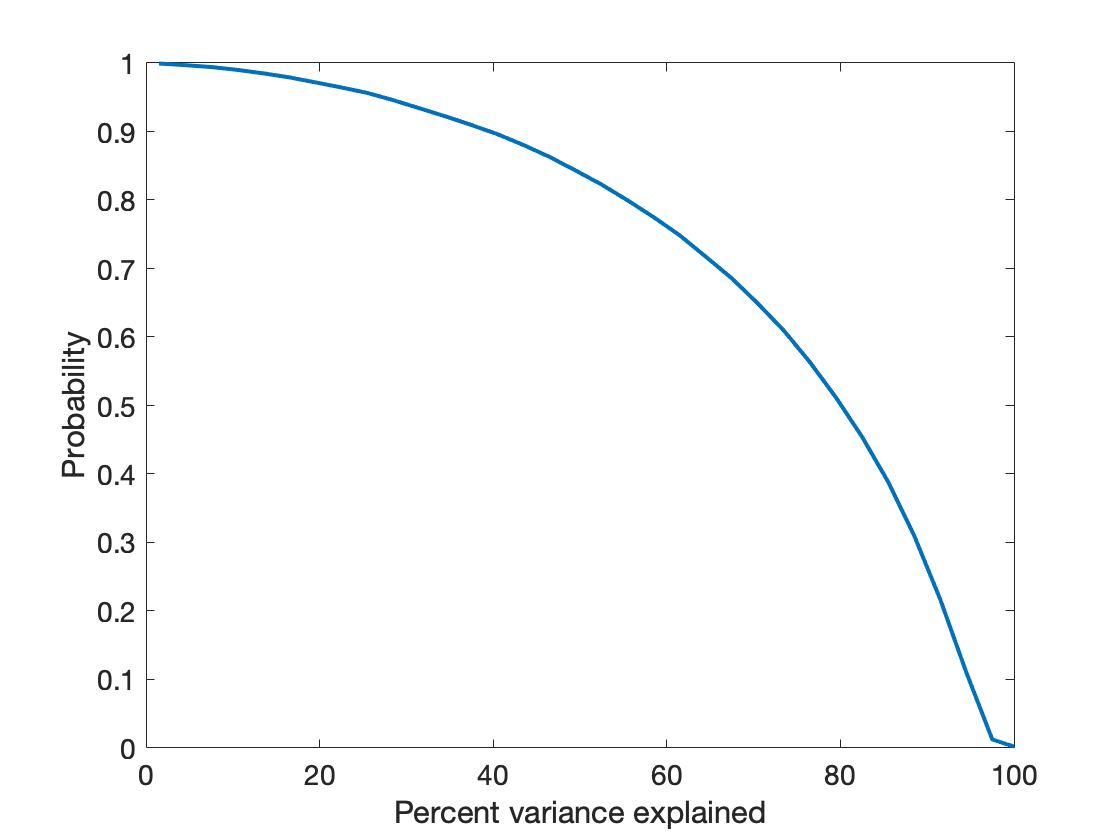

% plot cdf of percent variance explained
N4_cdf = zeros(size(N4));
for ii=1:length(N4)
    N4_cdf(ii) = sum(N4(1:ii).*de3(1:ii));
end

plot(centers, 1-N4_cdf, 'LineWidth', 2);
xlim([0, 100]) ;
set(gca, 'FontSize', 14)
ylabel('Probability');
xlabel('Percent variance explained')

Diagnose normality of projection field

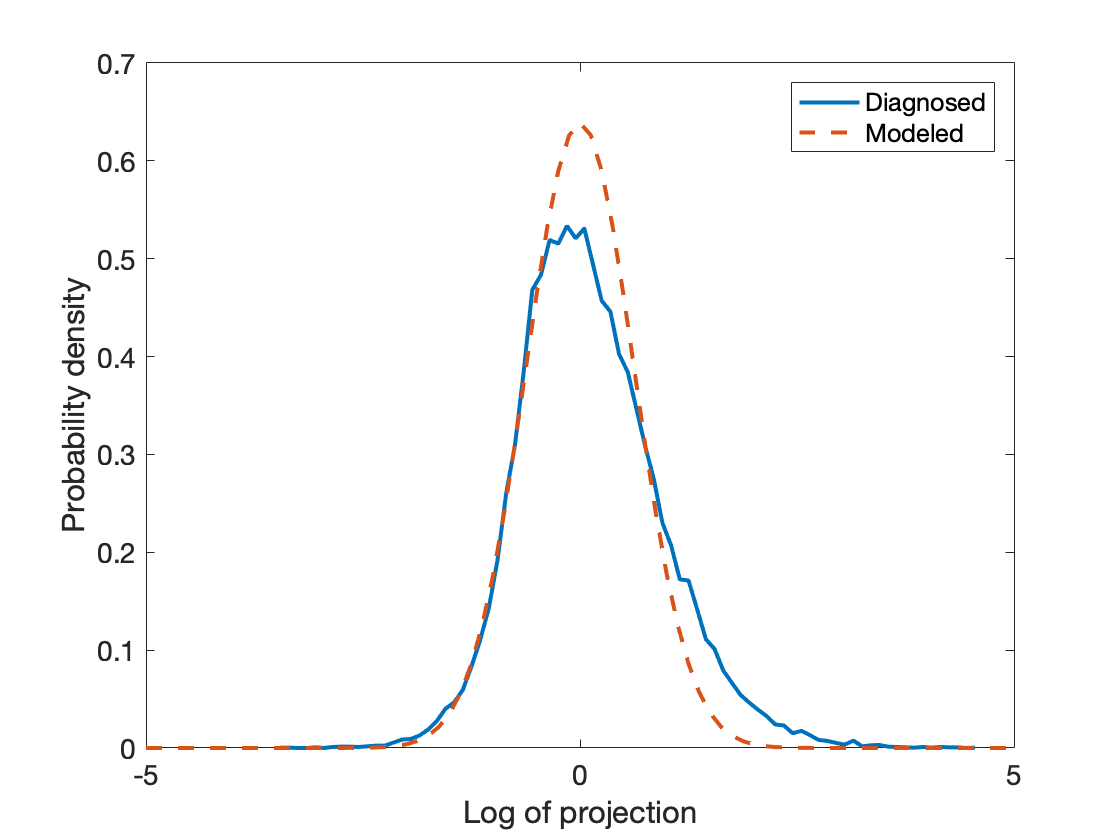

figure
[N,edges] = histcounts(log(proj_field(45:205, :, :)), 'Normalization','pdf');
edges = edges(2:end) - (edges(2)-edges(1))/2;
de = diff(edges);
N2 = N ./ sum(N(2:end).*de) ;
plot(edges, N2, 'LineWidth', 2);
xlim([-5, 5]) ;
set(gca, 'FontSize', 14)
ylabel('Probability density');
xlabel('Log of projection')

hold on
x = linspace(-5, 5, length(edges));
y = normpdf(x, 0, sqrt(0.39));
plot(x, y, '--', 'LineWidth', 2);
legend('Diagnosed', 'Modeled')
hold off

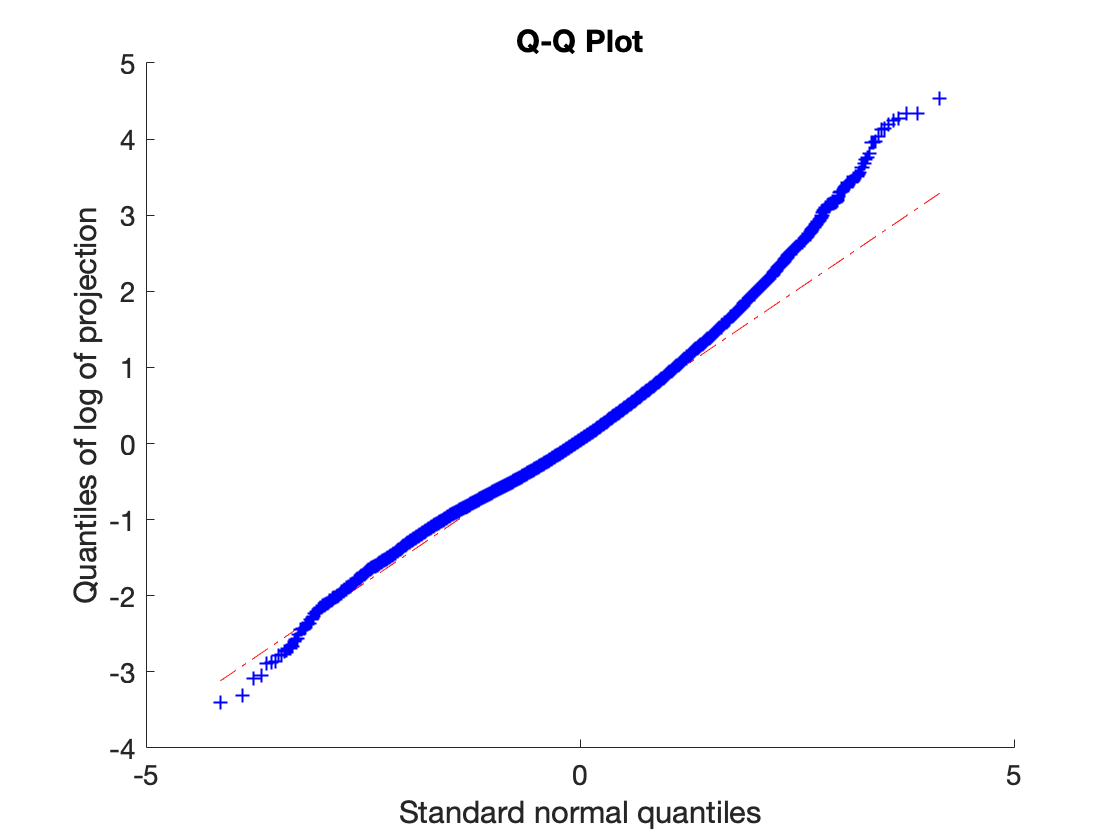


figure
this = log(proj_field(45:205, :, :));
qqplot(this(:))
set(gca, 'FontSize', 14)
title('Q-Q Plot')
ylabel('Quantiles of log of projection')
xlabel('Standard normal quantiles')

Calculate standard deviation and mean of log of projection field

mask = ~isnan(proj_field) & abs(ulat)<60;
s = std(log(proj_field(mask)));
mu = mean(log(proj_field(mask))); % mu = 0 in our model 
fprintf('The mean of the field is %.3f. The variance is %.3f.\n', mu, s^2)

The mean of the field is 0.085. The variance is 0.625.


fprintf('The mean of the log-normal distribution is %.3f.\n', exp(mu+0.5*s^2))

The mean of the log-normal distribution is 1.488.


fprintf('The median of the log-normal distribution is %.3f.\n', exp(mu))

The median of the log-normal distribution is 1.089.


fprintf('The mode of the log-normal distribution is %.3f.\n', exp(mu-s^2))

The mode of the log-normal distribution is 0.583.


## Temporal correlation

Our model for the decorrelation time is


$$\ln\left( \tau(x, y) \right) \approx b + \ln\left( \sqrt{\frac{\delta x^2 + \delta y^2}{\bar{u}^2(x,y) + \bar{v}^2(x,y)}} \right)$$


tau_mask = mask & ~isnan(tau+tau_energy) ;
b = mean( log(tau(tau_mask)) - log(tau_energy(tau_mask)) );
fprintf('The coefficient b in the model for decorrelation time is estimated to be %.2f', b)

The coefficient b in the model for decorrelation time is estimated to be 1.29

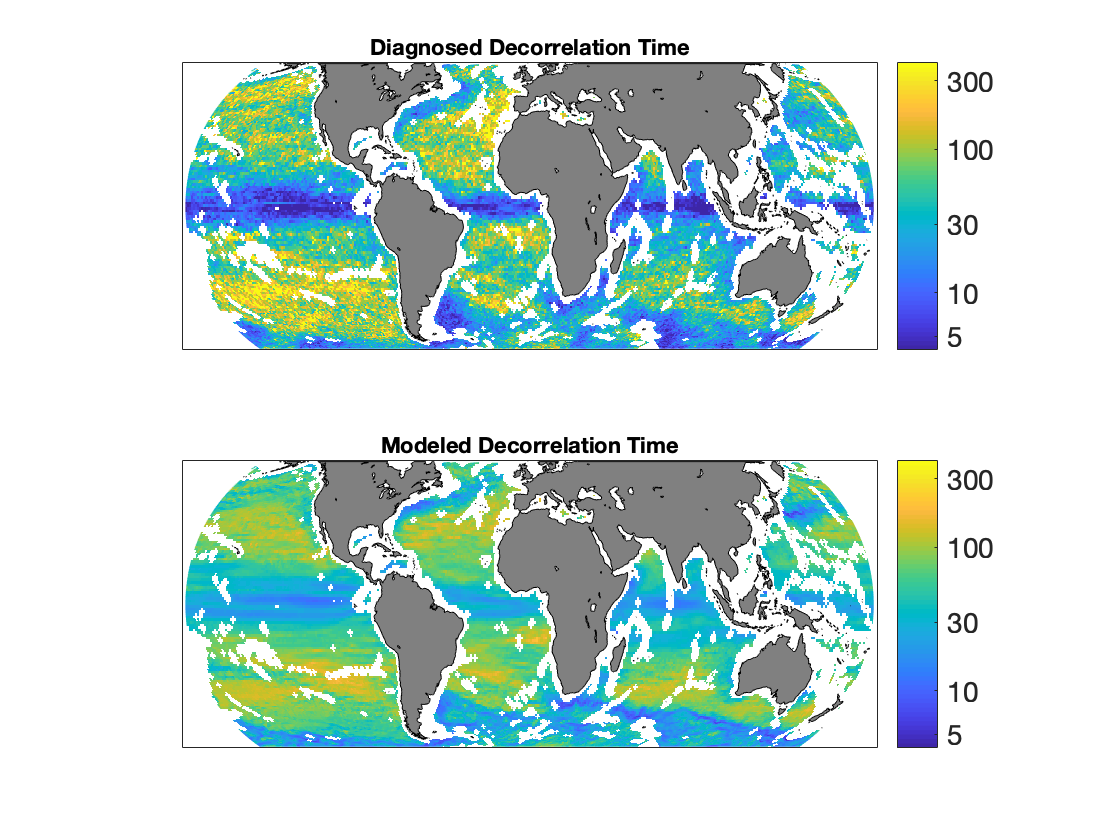

ulat2 = circshift(ulat, [0, 70]);
ulon2 = circshift(ulon, [0, 70]);

tau_2 = circshift(log10(tau), [0, 70]);
tau_2(isnan(tau_2)) = 0;
tau_energy_2 = circshift(log10(exp(b+log(tau_energy))), [0, 70]);
tau_energy_2(isnan(tau_energy_2)) = 0;

% estimated decorrelation time
figure
subplot(2,1,1)
axesm('eckert4', 'MapLatLim', [-60, 60]); 
framem; gridm; tightmap
t = geoshow(ulat2, ulon2, tau_2, 'DisplayType', 'texturemap') ;
colormap default
set(gca, 'clim', [log10(4) log10(400)])
geoshow('landareas.shp', 'FaceColor', [0.5 0.5 0.5] );
t.AlphaDataMapping = 'none'; % interpet alpha values as transparency values
t.FaceAlpha = 'texturemap'; % Indicate that the transparency can be different each pixel
alpha(t,double(circshift(new_mask, [0,70]))); 
title('Diagnosed Decorrelation Time')

% colorbar
cvals = [5, 10, 30, 100, 300] ;
cbar = colorbar('Ticks', log10(cvals), 'TickLabels', cvals);
cbar.FontSize = 14;

%grid
framem; tightmap; gridm;

% modeled decorrelation time
subplot(2,1,2)
axesm('eckert4', 'MapLatLim', [-60, 60]); 
framem; gridm; tightmap
t = geoshow(ulat2, ulon2, tau_energy_2, 'DisplayType', 'texturemap') ;
colormap default
set(gca, 'clim', [log10(4) log10(400)])
geoshow('landareas.shp', 'FaceColor', [0.5 0.5 0.5] );
t.AlphaDataMapping = 'none'; % interpet alpha values as transparency values
t.FaceAlpha = 'texturemap'; % Indicate that the transparency can be different each pixel
alpha(t,double(circshift(new_mask, [0,70]))); 
title('Modeled Decorrelation Time')

% colorbar
cvals = [5, 10, 30, 100, 300] ;
cbar = colorbar('Ticks', log10(cvals), 'TickLabels', cvals);
cbar.FontSize = 14;

%grid
framem; tightmap; gridm;

## Horizontal Spatial Correlation

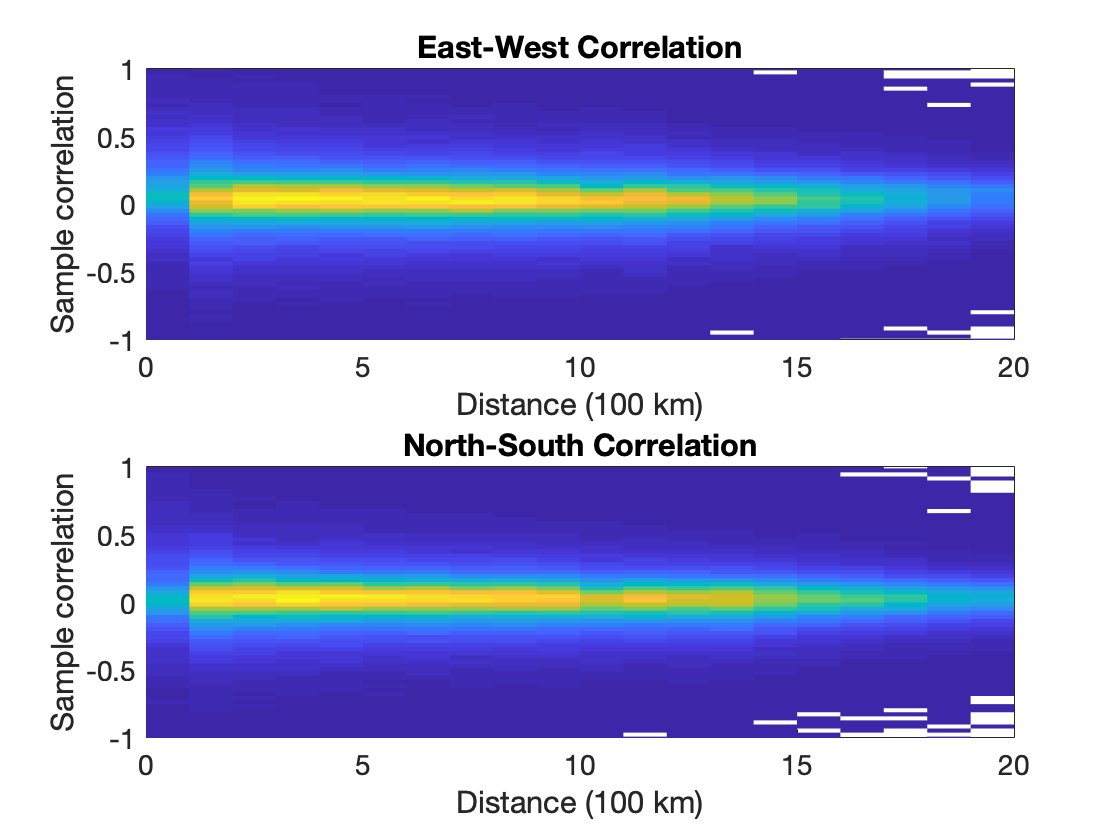

% plot east-west correlations
figure
subplot(2,1,1)
histogram2(EW_Dist, EW_Corr, 'DisplayStyle', 'tile') ;
ylim([-1 1]) ;
xlabel('Distance (100 km)') ;
ylabel('Sample correlation') ;
title('East-West Correlation') ;
xlim([0, 20])
set(gca,'fontsize', 14)


% plot north-south correlations
subplot(2,1,2)
histogram2(NS_Dist, NS_Corr, 'DisplayStyle', 'tile') ;
ylim([-1 1]) ;
xlabel('Distance (100 km)') ;
ylabel('Sample correlation') ;
title('North-South Correlation') ;
set(gca,'fontsize', 14)
xlim([0,20])